### Filtro Gradiente

Il gradiente di un' immagine misura la **direzione e l'intensità** del cambiamento dei valori dei pixel. Quindi dove nell'immagine i valori dei pixel cambiano velocemente, il valore del gradiente sarà maggiore. 

- **Derivata rispetto a x (Gx)**: trova i bordi verticali. [-1 , 1]

- **Derivata rispetto a y (Gy)**: trova i bordi orizzontali. [-1 ; 1]

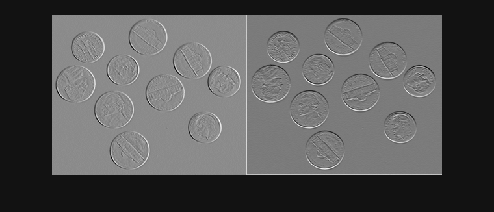

I = imread("imgs/coins.png");
I2 = imread("imgs/lena.png");
% Kernel per la derivata parzile in x e y
Kx = [-1, 1];
Ky = Kx';

% Applico la convoluzione per ottenere le due componenti del gradiente
Gx = conv2(I,Kx,"same");
Gy = conv2(I,Ky,"same");

imshowpair(Gx,Gy,"montage")

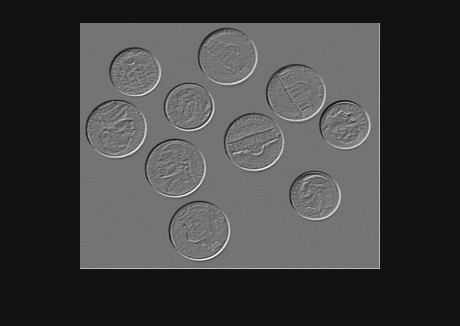

K_xy = Kx + Ky; % Combinazione delle componenti per gradiente
Gxy = conv2(I,K_xy,"same");
imshow(Gxy,[]);

Adesso posso calcolare il **MODULO** e l'**ORIENTAMENTO **del gradiente. Per mettere in evitdenza entrambi i bordi (x e y) usiamo il modulo del gradiente

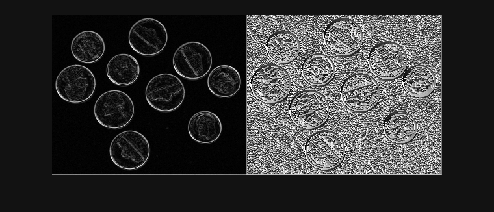

modulo = sqrt(Gx .^2 + Gy .^ 2); % quadrato pixel per pixel.
orientamento = atan2(Gy, Gx);
imshowpair(modulo,orientamento,"montage");

Possiamo calcolare la **direzione dei gradienti** dei bordi di un'immabine e visualizzare usando una mappa di colori codificata. 

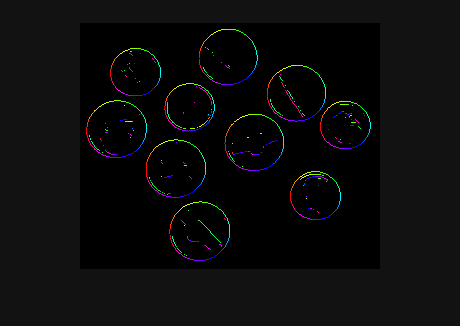

function myAngoloGradiente(img)

% Rilevamento bordi con sobel
[bordo,~,Gx,Gy] = edge(img,"sobel");

% Calcolo dell'angolo del gradiente
angolo = atan2(Gy,Gx); % da -pi a +pi

% Mappatura dell'angolo in un range discreto di colori (1-359)
direzione = round(358 * (angolo + pi) / (2*pi)) + 1; % da 0 a 2pi

% Machera sui bordi
direzione = direzione .* bordo;

figure; imshow(direzione,[[0,0,0];hsv(359)]);
end

myAngoloGradiente(I);

## Filtri di Prewitt e Sobel

Questi filtri migliorano il calcolo del gradiente introducendo un effetto di **media in direzione perpendicolare** a quella della derivata. Questo li rende più stabili in presenza di rumore. 

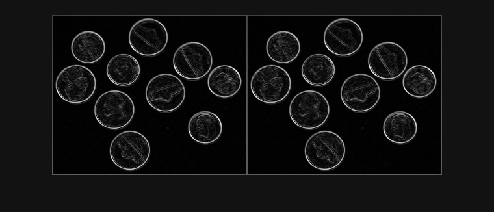

prewitt_x = fspecial("prewitt"); % Verticale 

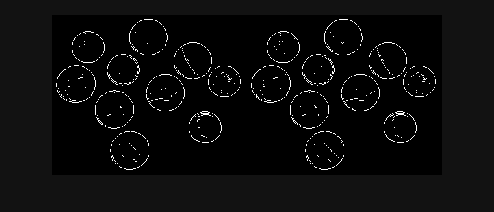

sobel_x = fspecial("sobel"); % più peso a riga/colonna centrale

% Filtro Prewitt
prewitt_gx = conv2(I,sobel_x,"same");
prewitt_gy = conv2(I,sobel_x',"same");

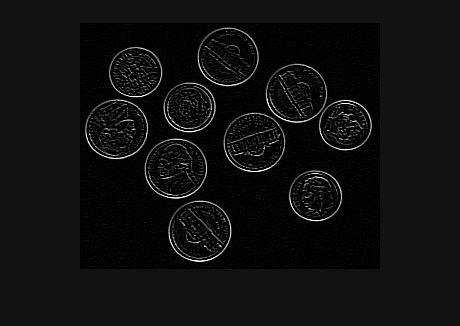

prewitt_modulo = sqrt(prewitt_gx .^2 + prewitt_gy .^ 2);

% Filtro Sobel
sobel_gx = conv2(I,sobel_x,"same");
sobel_gy = conv2(I,sobel_x',"same");
sobel_modulo = sqrt(sobel_gx .^2 + sobel_gy .^2);

figure; 
imshowpair(prewitt_modulo, sobel_modulo, "montage");

% La funzione "edge" calcola automaticamente modulo e bordi
bordi_sobel = edge(I,"sobel");
bordi_prewitt = edge(I,"prewitt");

figure;imshowpair(bordi_prewitt, bordi_sobel, "montage");

### Filtro Laplaciano

Il filtro Laplaciano (derivata seconda) cerca i punti di **passaggio per lo zero** della derivata prima. Individua i punti esatti in cui la pendenza cambia segno. Produce bordi molto sottili, ma è **molto sensibile al rumore.**

k_laplaciano_x = [1, -2, 1];
k_laplaciano_y = k_laplaciano_x';
k_laplaciano_xy = k_laplaciano_x + k_laplaciano_y;
% Applico il filtro Laplaciano per il rilevamento dei bordi
laplaciano = uint8(conv2(I, k_laplaciano_xy, "same"));

figure; imshow(laplaciano,[]);